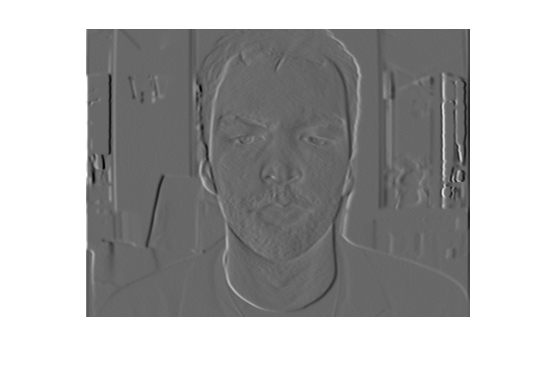

%provem de fer HOG amb una imatge
h = [-1 0 1];
h2 = [-1;0;1];

I = imread('BioID_0000.pgm');

%ndg = double(rgb2gray(I));
ndg = double(I);
ndg = imresize(ndg,[288 384]); %escalar a una mida multiple de 8
Hgrad = imfilter(ndg,h); %contorns horitzontals
Vgrad = imfilter(ndg,h2); %contorns verticals
imshow(Hgrad,[]);

%compute magnitude and angle of vectors
MAG = hypot(Vgrad,Hgrad); % magnitude = sqrt(V^2 + H^2)
D = Vgrad./Hgrad;
D(isnan(D))=0;
ANG = atand(D); %angle of each gradient vector
ANG = mod(ANG,180);

[F, C] = size(ndg);
cellH = 8;cellW = 8;
HOGs = cell((F/8),(C/8)); % matrix of histos of bins of pixels
for i = 1:(F/8)
    for j = 1:(C/8)
        HOGs{i,j} = zeros(1,9); %bins of 20 deg ranges
    end
end
%calculate vale of each cell: histogram of gradients of pixels
for i = 1:(F/8)
    for j = 1:(C/8)
        s = 0;
        for k = 1:cellH
            for m = 1:cellW
                %count value of gradient into histogram of cell
                deg =ANG(k+(i-1)*cellH,m+(j-1)*cellW);
                mag =MAG(k+(i-1)*cellH,m+(j-1)*cellW);
                %decide contribution to bins of deg
                %bins are 10 30 50 70 90 ....
                offset = mod(deg,20) - 10;
                %contributions to adjacent bins
                %one must always be 0
                bin = ceil(deg/20);
                if(bin==0)
                    bin = 1;
                end
                [left,right,center]=binContribs(offset);
                if(bin == 1)
                    HOGs{i,j}(9) = HOGs{i,j}(9) + left*deg;
                    HOGs{i,j}(bin) = HOGs{i,j}(bin) + center*deg;
                    HOGs{i,j}(bin+1) = HOGs{i,j}(bin+1) + right*deg;
                elseif(bin == 9)
                    HOGs{i,j}(bin-1) = HOGs{i,j}(bin-1) + left*deg;
                    HOGs{i,j}(bin) = HOGs{i,j}(bin) + center*deg;
                    HOGs{i,j}(1) = HOGs{i,j}(1) + right*deg;
                else
                    HOGs{i,j}(bin-1) = HOGs{i,j}(bin-1) + left*deg;
                    HOGs{i,j}(bin) = HOGs{i,j}(bin) + center*deg;
                    HOGs{i,j}(bin+1) = HOGs{i,j}(bin+1) + right*deg;
                end
            end
        end
    end
end

%BLOCK NORMALIZATION OF overlapping 2X2 CELLS
[n, m] = size(HOGs);
normHOGs = cell(n-1,m-1); % matrix of normalized blocks of hists
for i = 1:n-1
    for j = 1:m-1
        normHOGs{i,j} = zeros(1,36); %bins of 20 deg ranges
    end
end

for i = 1:n-1
    for j = 1:m-1
        normHOGs{i,j} = [HOGs{i,j} HOGs{i,j+1} HOGs{i+1,j} HOGs{i+1,j+1}];
        normHOGs{i,j} = normHOGs{i,j} / norm(normHOGs{i,j}); %normalize
    end
end

%FINALLY: THE DESCRIPTOR OF THE IMAGE IS THE NORMALIZED HISTOGRAM MATRIX
%normHOGs. 